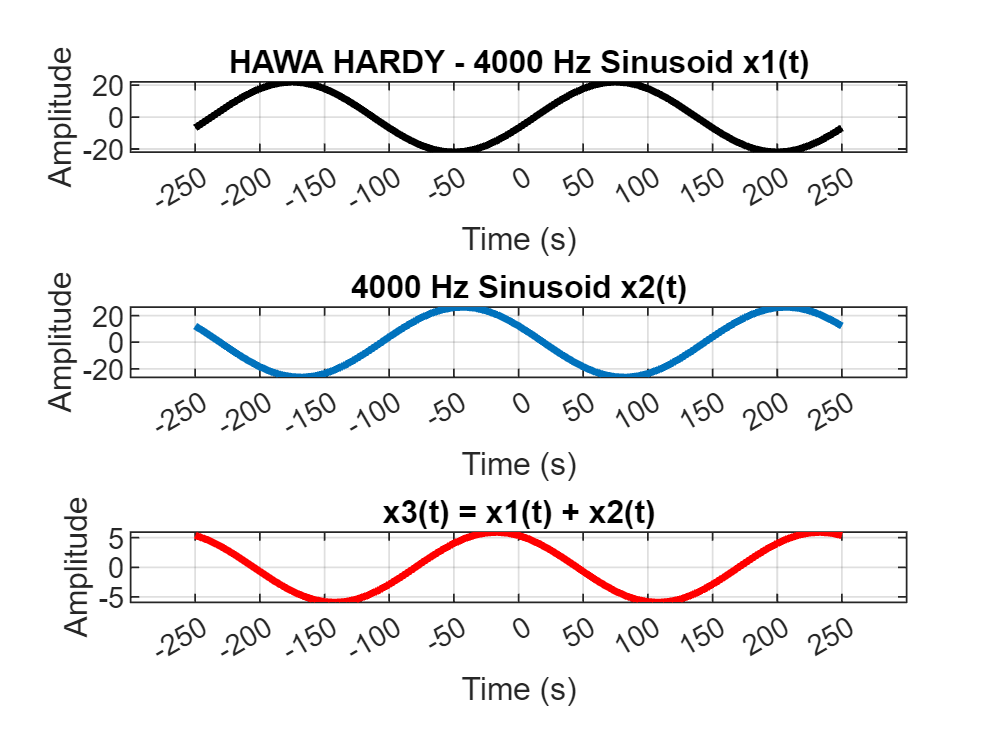

% Parameters
Freq = 4000;          % Frequency of the sinusoids in Hz
T = 1/Freq;           % Period of the sinusoid
samples = 30;         % Number of samples per period
step = T/samples;

% Generate time vector tt from -T to T with sufficient samples
tt = -T : step : T;

% Amplitudes
A1 = 22;              % My Age
A2 = 1.2 * A1;        % 1.2 times age

% Time shifts
D = 19;               % Day of birth
M = 4;                % Month of birth
tm1 = (37.2 / M) * T; % Time shift for x1
tm2 = -(41.3 / D) * T;% Time shift for x2

% Generate the sinusoids
x1 = A1 * cos(2 * pi * Freq * (tt - tm1));
x2 = A2 * cos(2 * pi * Freq * (tt - tm2));
% Third Sinusoid
x3 = x1 + x2;

% Plotting
figure; % Creating new figure window

% Plot x1(t)
subplot(3,1,1);
plot(tt/1e-6, x1, 'k', 'LineWidth', 2); grid on;
title('HAWA HARDY - 4000 Hz Sinusoid x1(t)');
xlabel('Time (s)');
ylabel('Amplitude');
xticks([-T/1e-6 : 50 : T/1e-6]) % set x-axis ticks to every 50 microseconds

% Plot x2(t)
subplot(3, 1, 2);
plot(tt/1e-6, x2, 'LineWidth', 2);
title('4000 Hz Sinusoid x2(t)');
xticks([-T/1e-6 : 50 : T/1e-6])
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot x3(t)
subplot(3, 1, 3);
plot(tt/1e-6, x3, 'r', 'LineWidth', 2);
title('x3(t) = x1(t) + x2(t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on; 
xticks([-T/1e-6 : 50 : T/1e-6])

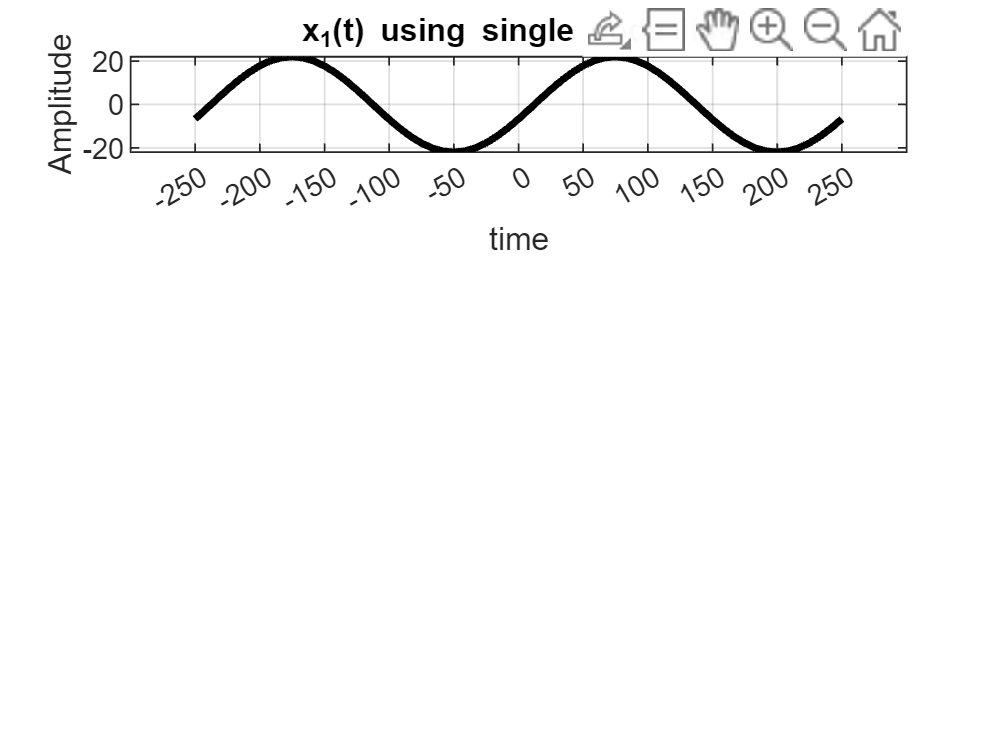


%----- Complex Amplitude
phi1 = -1.88;                       % phase in radians
x1 = real(A1*exp(1j*phi1).*exp(1j*2*pi*4000*tt)); %single code line

figure;
subplot(3,1,1);
plot(tt/1e-6, x1, 'k','Linewidth', 2); grid on
ylabel('Amplitude'); xlabel('time');
title('x_1(t) using single code line', 'FontWeight', 'Bold')
xticks([-T/1e-6 : 50 : T/1e-6])  % Sets x-axis ticks to every 50 microseconds